# Changes status randomly at pipes during simulation.

## This example contains: 

- Load a network. 

- Get pipe count. 

- Get pipe indices. 

- Run step by step hydraulic analysis. 

- Set status random 0/1 for pipes. 

- Plot flows. 

- Unload library.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.
EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


ans = int32
   11


EPANET Class is unloaded


## Load a network.

d = epanet('Net1.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Get pipe count.

pipe_count = d.getLinkPipeCount;

## Get pipe indices.

pipe_indices = d.getLinkPipeIndex;

## Run step by step hydraulic analysis.

d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis;
i=1;tstep=1; F=[];
while (tstep>0)
    % Set status random 0/1 for pipes.
    Status = round(rand(1,pipe_count))';

    t=d.runHydraulicAnalysis;
    d.setLinkStatus(pipe_indices, Status); i=i+1;
    F = [F; d.getLinkFlows];
    tstep=d.nextHydraulicAnalysisStep;
end
d.closeHydraulicAnalysis;

## Plot flows.

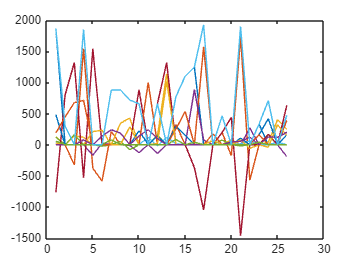

plot(F)

## Unload library.

d.unload

EPANET Class is unloaded
